 
A{1,1} =
 
     1     0
     0     1

 
 
A{2,1} =
 
   -10    15
     0    -3

 
 
A{1,2} =
 
    -5     0
     0     1

 
 
A{2,2} =
 
   -10   -15
     0    -3

 


 
P{1,1} =
 
   -0.0069   -0.0020
   -0.0020   -0.0526

 
 
P{2,1} =
 
    0.0403   -0.0000
   -0.0000    0.1876

 
 
P{1,2} =
 
    0.0413    0.0075
    0.0075    0.1820

 
 
P{2,2} =
 
   1.0e-17 *

    0.2260   -0.0983
   -0.0983         0

 


LM = 0.0318

C =     0.1300    0.8535    0.8000    0.7000    0.6000    0.5000    0.4000    0.3000    0.2000    0.1000         0   -0.1000   -0.2000   -0.3000   -0.4000   -0.5000   -0.6000   -0.7000   -0.7524   -0.8000   -0.9000   -1.0000   -1.1000   -1.2000   -1.3000   -1.3307   -1.4000   -1.5000   -1.6000   -1.7000   -1.7082   -1.8000   -1.9000   -2.0000   -2.0002   -2.1000   -2.2000   -2.2393   -2.3000   -2.4000   -2.4431   -2.5000   -2.6000   -2.6195   -2.7000   -2.7730   -2.8000   -2.9000   -2.9083   -3.0000
  217.0000   -1.8000   -1.8059   -1.8157   -1.8242   -1.8314   -1.8371   -1.8415   -1.8445   -1.8460   -1.8461   -1.8447   -1.8418   -1.8375   -1.8317   -1.8245   -1.8159   -1.8060   -1.8000   -1.7937   -1.7790   -1.7628   -1.7453   -1.7266   -1.7066   -1.7000   -1.6830   -1.6572   -1.6303   -1.6024   -1.6000   -1.5693   -1.5350   -1.5001   -1.5000   -1.4587   -1.4169   -1.4000   -1.3707   -1.3216   -1.3000   -1.2681   -1.2114   -1.2000   -1.1478   -1.1000   -1.0804   -1.0064   -1.0000   -0

h =   Contour with properties:

    LineColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 2
         Fill: off
    LevelList: 0.1300
        XData: [101×101 double]
        YData: [101×101 double]
        ZData: [101×101 double]

  Show all properties


C2 =     0.4900    1.2556    1.2000    1.1000    1.0000    0.9000    0.8000    0.7000    0.6000    0.5000    0.4000    0.3000    0.2000    0.1000         0   -0.1000   -0.2000   -0.3000   -0.4000   -0.5000   -0.6000   -0.7000   -0.8000   -0.9000   -1.0000   -1.1000   -1.1138   -1.2000   -1.3000   -1.4000   -1.5000   -1.6000   -1.7000   -1.7106   -1.8000   -1.9000   -2.0000   -2.1000   -2.1337   -2.2000   -2.3000   -2.4000   -2.4734   -2.5000   -2.6000   -2.7000   -2.7600   -2.8000   -2.9000   -3.0000
  301.0000   -2.5000   -2.5067   -2.5177   -2.5279   -2.5371   -2.5453   -2.5525   -2.5588   -2.5640   -2.5681   -2.5712   -2.5732   -2.5741   -2.5740   -2.5728   -2.5704   -2.5670   -2.5625   -2.5570   -2.5503   -2.5427   -2.5339   -2.5242   -2.5135   -2.5018   -2.5000   -2.4878   -2.4725   -2.4563   -2.4392   -2.4211   -2.4021   -2.4000   -2.3802   -2.3572   -2.3333   -2.3087   -2.3000   -2.2813   -2.2522   -2.2224   -2.2000   -2.1911   -2.1566   -2.1215   -2.1000   -2.0844   -2.0443   -

h2 =   Contour with properties:

    LineColor: [0.5000 0.5000 0.5000]
    LineStyle: '-'
    LineWidth: 2
         Fill: off
    LevelList: 0.4900
        XData: [101×101 double]
        YData: [101×101 double]
        ZData: [101×101 double]

  Show all properties


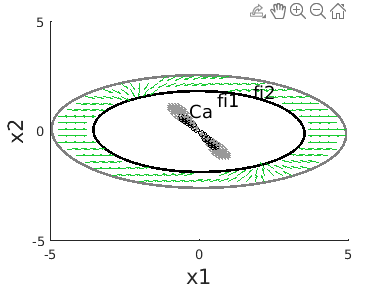

% ROTINA USADA PARA SIMULAR O SISTEMA FUZZY DO EXEMPLO 1
% -------------------------------------------------------------------
% Limpeza de memória
close all;
clear all;
clc;
% PARÂMETROS DO PROBLEMA
ri=2;
Ns=2; %numero de sistemas chaveamento
% Parâmetros do sistema
% Parametros usados na combinação convexa
alfa=[0.6 0.4];
beta=1;
xv=5; %modulo dos limites do conj Z
gama=0.19;  % Usado nas LMIs para limitar as matrizes P_pk
lamb=.02; % Restriçao na taxa de decaimento
A = cell(Ns,ri);

% Modelo ALTERADO 10/03/2017
A{1,1}=[1 0;0 1];
A{1,2}=[-5 0;0 1];
A{2,1}=[-10 15;0 -3];
A{2,2}=[-10 -15;0 -3];


% -------------------------------------------------------------------
P = lmi_chav_fuzzychaveado(A,alfa,beta,xv,gama)
if ~isempty(P)
  celldisp(A)
  celldisp(P)
  dlim = [-xv xv];
  % Exibindo a região onde Vponto é positiva e calculando o máximo da
  % da V nessa região
  [x1,x2] = meshgrid(dlim(1):.1:dlim(2),dlim(1):.1:dlim(2));
  [tF1,tF2]=size(x1);
  figure(1);
  hold on;
  VO=[];  DVH=[];
  for t1=1:tF1
     for t2=1:tF2
        XT=[x1(t1,t2);x2(t1,t2)]; % Vetor de estado.
        % Funções de pertinência
        h12=(x1(t1,t2)^2+x2(t1,t2)^2)/50; h11=1-h12;
        h21=(x2(t1,t2)^2)/25;  h22=1-h21;

        PT = h12*P{1,2}+h21*P{2,1};
        VO(t1,t2) =  XT'*PT*XT;
        Ah1=h11*A{1,1}+h12*A{1,2};
        Ah2=h21*A{2,1}+h22*A{2,2};        
        S1=Ah1*XT; % Subsistema 1
        S2=Ah2*XT; % Subsistema 2
         S=alfa(1)*S1+alfa(2)*S2;
        dh12=(x1(t1,t2)*(alfa(1)*S1(1)+alfa(2)*S2(1))+x2(t1,t2)*(alfa(1)*S1(2)+alfa(2)*S2(2)))/25; % h12ponto
        dh21=2*x2(t1,t2)*(alfa(1)*S1(2)+alfa(2)*S2(2))/25;
        PHX=XT'*(dh12*P{1,2}+dh21*P{2,1})*XT;
        if  (PHX > 0)
           %plot(x1(t1,t2),x2(t1,t2),'b*','MarkerSize',3)
           plot(x1(t1,t2),x2(t1,t2),'*','Color',[0.6 0.6 0.6],'MarkerSize',3)
           DVH= [DVH VO(t1,t2)];
        end        
        VPONTO=S'*PT*XT+XT'*PT*S+PHX;
        if VPONTO>0
           plot(x1(t1,t2),x2(t1,t2),'ko','MarkerSize',5)
           DVH= [DVH VO(t1,t2)];
        end            
     end
  end
LM=max(DVH)
LM=0.13; %0.13>LM anterior
% LM=0.161;
[C,h]=contour(x1,x2,VO,[LM,LM],'k-','LineWidth',2)
[C2,h2]=contour(x1,x2,VO,[0.49001,0.49001],'Color',[0.5 0.5 0.5],'LineWidth',2)

  [x1,x2] = meshgrid(dlim(1):.3:dlim(2),dlim(1):.3:dlim(2));
  [tF1,tF2]=size(x1);
  % Laço usado para criar o retrato de fase do sistema fuzzy
  VO=[];  DVH=[];
  LM=1.4*LM;
  for t1=1:tF1
     for t2=1:tF2
        XT=[x1(t1,t2);x2(t1,t2)]; % Vetor de estado.
        % Funções de pertinência
        h12=(x1(t1,t2)^2+x2(t1,t2)^2)/50; h11=1-h12;
        h21=(x2(t1,t2)^2)/25;  h22=1-h21;
        Ah1=h11*A{1,1}+h12*A{1,2};
        Ah2=h21*A{2,1}+h22*A{2,2};        
        S1=Ah1*XT; % Subsistema 1
        S2=Ah2*XT; % Subsistema 2         
%         dh12=(x1(t1,t2)*S1(1)+x2(t1,t2)*S1(2))/25; % h12ponto
%         dh21=2*x2(t1,t2)*S2(2)/25;
        dh12=(x1(t1,t2)*(alfa(1)*S1(1)+alfa(2)*S2(1))+x2(t1,t2)*(alfa(1)*S1(2)+alfa(2)*S2(2)))/25; % h12ponto
        dh21=2*x2(t1,t2)*(alfa(1)*S1(2)+alfa(2)*S2(2))/25;
        PT = h12*P{1,2}+h21*P{2,1};
        VO =  XT'*PT*XT;
        DPh=dh12*P{1,2}+dh21*P{2,1};
        DV1=XT'*DPh*XT+2*XT'*PT*S1; % Derivada da V no subsistema 1
        DV2=XT'*DPh*XT+2*XT'*PT*S2; % Derivada da V no subsistema 2
        if (VO > LM)  & (VO < 0.49001)
%            plot(x1(t1,t2),x2(t1,t2),'g*','MarkerSize',3);
%            plot(x1(t1,t2),x2(t1,t2),'*','Color',[0.6 0.6 0.6],'MarkerSize',3)
           if  DV1 < DV2
                dx1(t1,t2)=S1(1);
                dx2(t1,t2)=S1(2);
           else
                dx1(t1,t2)=S2(1);
                dx2(t1,t2)=S2(2);
           end
        else
                x1(t1,t2)=0;
                x2(t1,t2)=0;
                dx1(t1,t2)=0;
                dx2(t1,t2)=0;
        end
     end
  end

  sz = sqrt(dx1.^2 + dx2.^2); % The length of each arrow.
  dx1=dx1./sz;
  dx2=dx2./sz;
  quiver(x1,x2,dx1,dx2,1,'-','Color',[0.1 .8 0.2])
  xlabel('x1','fontsize',16);
  ylabel('x2','fontsize',16);
  text(0.6038,1.4054,'fi1','fontsize',14,'fontname','helvetica')
  text(1.8055,1.76,'fi2','fontsize',14,'fontname','helvetica')
  text(-0.3289,0.8889,'Ca','fontsize',14,'fontname','helvetica')

  
  % % CONDIÇÕES INICIAIS USADAS NAS SIMULAÇÕES DOS SUBSISTEMAS
X01=[-3;-1];
X02=[3.5;0.8];

## Simulando o sistema fuzzy chaveado para a condição inicial X01

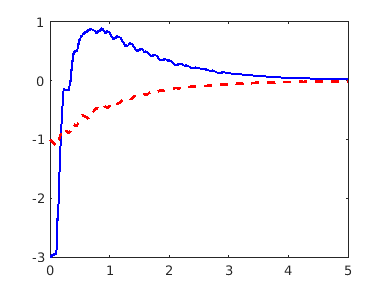

TF=5;
Tempo=[0:.001:TF];
Laux=[];
Taux=[];
CHMIN = 100; % Número máximo de iterações que um sistema pode ficar ativo
step=1;
global xsw at CHR1 CHR2;
at=1;  % Variavel diz qual o sistema q está ativo;
xsw=1; % Variavel controla o numero maximo de iterações que um sistema permanece ativo;
CHR1=CHMIN;
%rng(19);
CHR2=CHMIN;
save ex2.mat Laux Taux;
save ex2APMfi.mat A P LM CHMIN
y=ode1('exemplo_2_ODE',Tempo,X01);
St=length(Tempo);
figure(2);
plot(Tempo(1:step:St),y(1:step:St,1),'b-',...
     Tempo(1:step:St),y(1:step:St,2),'r--','LineWidth',2)

## Gerando o gráfico da lei de chaveamento

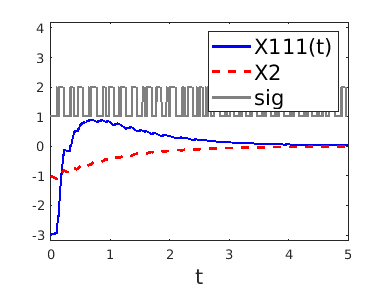

load ex2.mat Laux Taux;
STaux=length(Taux);
hold on
plot(Taux(1:step:STaux),Laux(1:step:STaux),'-','Color',[0.5 0.5 0.5],'LineWidth',2)
%plot(Taux(1:step:STaux),Laux(1:step:STaux),'b','LineWidth',2)
xlabel('t','fontsize',16);
hleg= legend('X111(t)','X2','sig');
set(hleg,'fontsize',16,'fontname','helvetica');
axis([-.01 TF X01(1)-.2 4.2]);

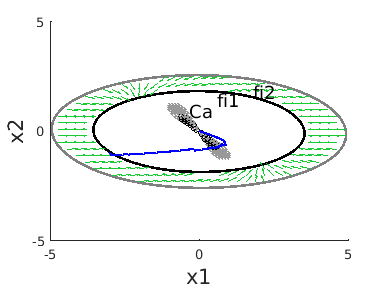


figure(1)
 hold on
 plot(y(1:step:St,1),y(1:step:St,2),'b-','LineWidth',2)

## Gerando o gráfico da Função de Lyapunov

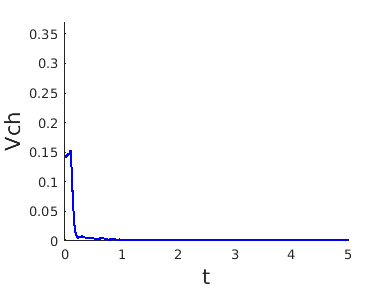

 for i=1:St,
    % Definindo as funções de pertinência do Subsistema 1
    h12=(y(i,1)^2+y(i,2)^2)/50;
    h11=1-h12;
    h21=(y(i,2)^2)/25;
    h22=1-h21;
    Vc(i)=[y(i,1) y(i,2)]*(h12*P{1,2}+h21*P{2,1})*[y(i,1);y(i,2)];
end
figure(3)
hold on
plot(Tempo,Vc,'b','LineWidth',2)
xlabel('t','fontsize',16)
ylabel('Vch','fontsize',16)
axis([-.02 TF 0 0.37])

## Simulando o sistema fuzzy chaveado para a condição inicial X02

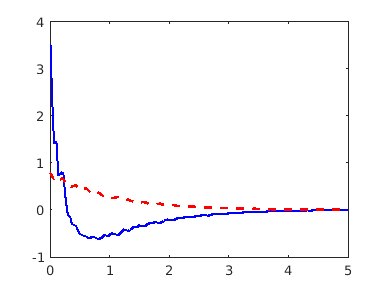

Laux=[]; Taux=[];
save ex2.mat Laux Taux;
y=ode1('exemplo_2_ODE',Tempo,X02);
St=length(Tempo);
figure(4);
plot(Tempo(1:step:St),y(1:step:St,1),'b-',...
     Tempo(1:step:St),y(1:step:St,2),'r--','LineWidth',2)

## Gerando o gráfico da lei de chaveamento

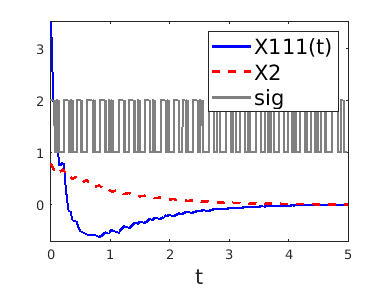

load ex2.mat Laux Taux;
STaux=length(Taux);
hold on
% plot(Taux(1:step:STaux),Laux(1:step:STaux),'b','LineWidth',2)
plot(Taux(1:step:STaux),Laux(1:step:STaux),'-','Color',[0.5 0.5 0.5],'LineWidth',2)
xlabel('t','fontsize',16);
hleg= legend('X111(t)','X2','sig');
set(hleg,'fontsize',16,'fontname','helvetica');
axis([-.01 TF -.7 3.51]);

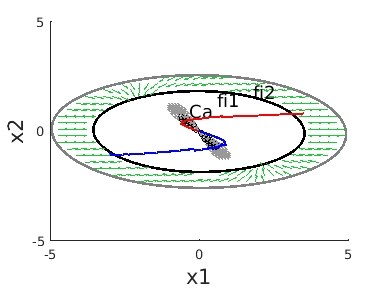


figure(1)
 hold on
 plot(y(1:step:St,1),y(1:step:St,2),'r-','LineWidth',2)

## Gerando o gráfico da Função de Lyapunov

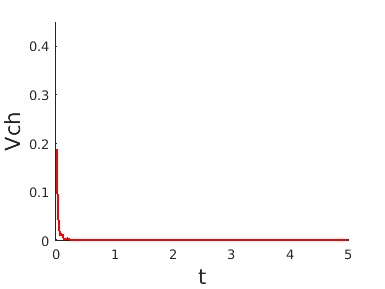

 for i=1:St,
    % Definindo as funções de pertinência do Subsistema 1
    h12=(y(i,1)^2+y(i,2)^2)/50;
    h11=1-h12;
    h21=(y(i,2)^2)/25;
    h22=1-h21;
    Vc(i)=[y(i,1) y(i,2)]*(h12*P{1,2}+h21*P{2,1})*[y(i,1);y(i,2)];
end
figure(5)
hold on
plot(Tempo,Vc,'r','LineWidth',2)
xlabel('t','fontsize',16)
ylabel('Vch','fontsize',16)
axis([-.02 TF 0 0.45])


% Autovalor_subsitema1 = [eig(A{1,1}) eig(A{1,2})]
% Autovalor_subsitema2 = [eig(A{2,1}) eig(A{2,2})]
else
     display('Lmis infactiveis')
end